# Asynchronous Angle-only Tracking with GM-PHD Tracker

This example shows you how to track objects using angle-only measurements from spatially distributed and asynchronous passive sensors. Angle-only measurements from a single sensor provide incomplete observability for estimating the state of an object. When working with angle-only measurements, there are two main methods to completely observe the object state. In the case of a single sensor, the sensing platform needs to out-maneuver the object to obtain range information. Alternatively, you can use multiple spatially distributed passive sensors to gain observability of the object state

You can find the single sensor workflow in 

[Passive Ranging Using a Single Maneuvering Sensor](docid:fusion_ug#mw_fc76d4f5-2549-41ae-a719-a88f09c787f6) example. For the case that angle-only measurements from multiple sensors are received at the same time (synchronous sensors), you can use a *static fusion before tracking* [1] architecture illustrated in the [Tracking Using Distributed Synchronous Passive Sensors](docid:fusion_ug#mw_d80cd5a4-9089-495b-85f8-e3f63ec30780) example. In this example, you track objects using asynchronous passive sensors, which do not provide information at the same timestamp.

## Introduction

In the asynchronous multi-sensor angle-only tracking problem, since detections from all sensors are not available at the same time step, the prior distribution of object states must be modeled by using detections from a single sensor. A popular technique to initialize prior distribution using angle-only detections is by using range-parameterization. The range-parameterization technique defines the prior distribution as a Gaussian mixture and initializes many Gaussian components at different range hypothesis for the object. The range-parameterization process from a single angle-only detection is shown in the image below. 

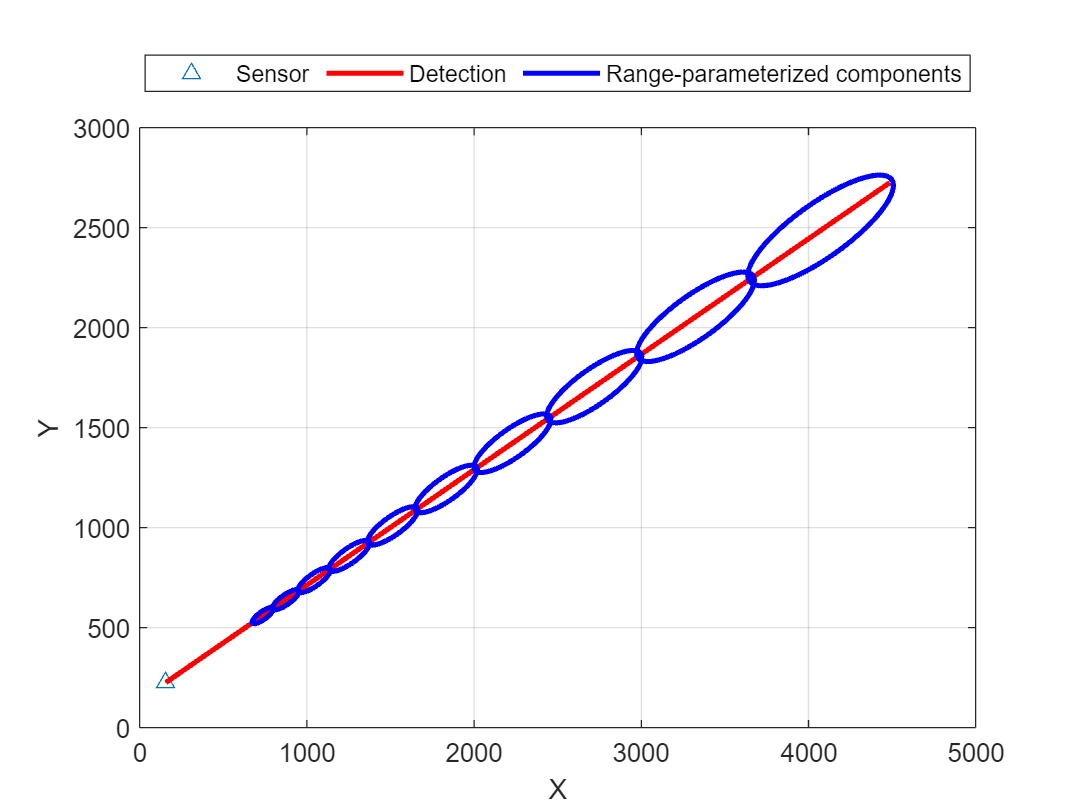

helperAsyncAngleOnlyTrackingDisplay.plotRangeParameterization();

The formulation of Gaussian mixture probability hypothesis density (GM-PHD) filter offers a natural approach to integrate the range-parameterization. By using the range-parameterization technique to describe the adaptive birth intensity of the GM-PHD filter, you can model the prior distribution using angle-only measurements from a single sensor [2]. When the filter is updated with detections from other sensors, this prior distribution has higher likelihood of being closer to the intersections of angle-only measurements. As multiple angle-only measurements can intersect at both true and ghost object locations, the GM-PHD filter tries to disambiguate between them using two main sources of information. First, components at true target locations have higher likelihood to associate with measurements from multiple sensors than those at ghost locations. Second, components at ghost object locations may deviate from the expected prior motion model defined for the objects.

## Setup Scenario

In this example, you use a similar scenario as shown in the [Tracking Using Distributed Synchronous Passive Sensors](docid:fusion_ug#mw_d80cd5a4-9089-495b-85f8-e3f63ec30780) example. The relative placement of sensors and objects in this scenario is same as that of an example in [1]. The scenario consists of five equally-spaced objects observed by three passive sensors. You use the [`radarEmitter`](docid:fusion_ref#mw_53fba034-3809-4a3a-b929-5ec8e814901f) object and the [`fusionRadarSensor`](docid:fusion_ref#mw_bb0f1b31-d268-48c6-aecd-8348f6adc953) to simulate radar emission and detection respectively. Set the `DetectionMode` property of `fusionRadarSensor` to `ESM` to model a passive radar sensor. Each sensor has a field of view of 180 degrees in azimuth and produces about 2 to 3 false alarms per step. The sensor update rate is 1 Hz and the sensors have a clock offset of 1/3 seconds between each other. The `HasNoise` property of the sensors is set to `false` to first generate noise-free detections. After that, you add white noise with a variance of 2 square degrees to the measurements. Note that the estimation accuracy and ghost disambiguation highly depends on the measurement accuracy. For more details on scenario creation, refer to the helper function, `helperCreatePassiveAsyncScenario`, attached with this example. 

% For reproducible results
rng(2022)

% Create scenario
scenario = helperCreatePassiveAsyncScenario;

% Create display
display = helperAsyncAngleOnlyTrackingDisplay;

## **Setup Tracker and Metric**

In this section, you set up a Gaussian-mixture probability hypothesis density (GM-PHD) multi-object tracker to track the objects using angle-only measurements from asynchronous sensors. You also set up the OSPA-on-OSPA (Optimal Subpattern Assignment) or OSPA(2) metric [3] to evaluate results from the tracker based on the simulated ground truth. 

**GM-PHD Tracker**

You configure the tracker using the [trackerPHD](docid:fusion_ref#mw_b4f176b8-c38d-4afb-97af-6e7909c2337a) System Object™. The `trackerPHD` object requires the definition of sensor configurations as [`trackingSensorConfiguration`](docid:fusion_ref#mw_5d11e16c-fdec-4503-ab34-40d875e5bdf9) objects. You can obtain this information from the simulated sensor models in the scenario. In addition to that, you also define the range-parameterized birth intensity by setting the `FilterInitializationFcn` to the helper function, `initcvAngleOnlyGMPHD`, included in this example script. This function creates range-parameterized Gaussian mixture with 10 components ranging from 600 and 5000 meters from the sensor. You use these sensor configurations to construct the PHD tracker. 

% Construct sensor configurations
sensorConfigs = trackingSensorConfiguration(scenario,...
    FilterInitializationFcn=@initcvAngleOnlyGMPHD);

% Construct tracker 
tracker = trackerPHD(SensorConfigurations=sensorConfigs,...
    HasSensorConfigurationsInput=true,...
    BirthRate=0.1,...
    MaxNumComponents=5000,...
    ExtractionThreshold=0.85,...
    ConfirmationThreshold=0.95);

**OSPA(2) metric**

You setup the OSPA(2) metric to measure the performance of the tracker. The OSPA(2) metric allows you to evaluate the tracking performance over a history of tracks as opposed to instantaneous results in the traditional OSPA metric. As a result, the OSPA(2) metric penalizes phenomenon such as track switching and fragmentation more consistently. You configure the OSPA(2) metric by using the [trackOSPAMetric](docid:fusion_ref#mw_5889038b-d92d-4839-81d3-8bc2ebeb1eb3) object and setting the `Metric` property to `"OSPA(2)"`. You choose absolute error in position as the base distance between a track and truth at a time instant by setting the `Distance` property to `"posabserr"`.

% Define OSPA metric calculator
ospaMetric = trackOSPAMetric(Metric="OSPA(2)",...
    Distance="posabserr",...
    WindowLength=25,...
    CutoffDistance=150);

## **Run Scenario and Track Objects**

In this section, you run the scenario in a loop, generate data from asynchronous sensors and feed the data to the multi-object tracker. For qualitative assessment of tracking performance, you visualize the ground truth and the estimated tracks. Further, to understand how the PHD tracker can discriminate between ghosts and true objects, you plot the PHD estimate in the 2-D position space. For quantitative assessment of the tracking performance, you evaluate the OSPA(2) metric.

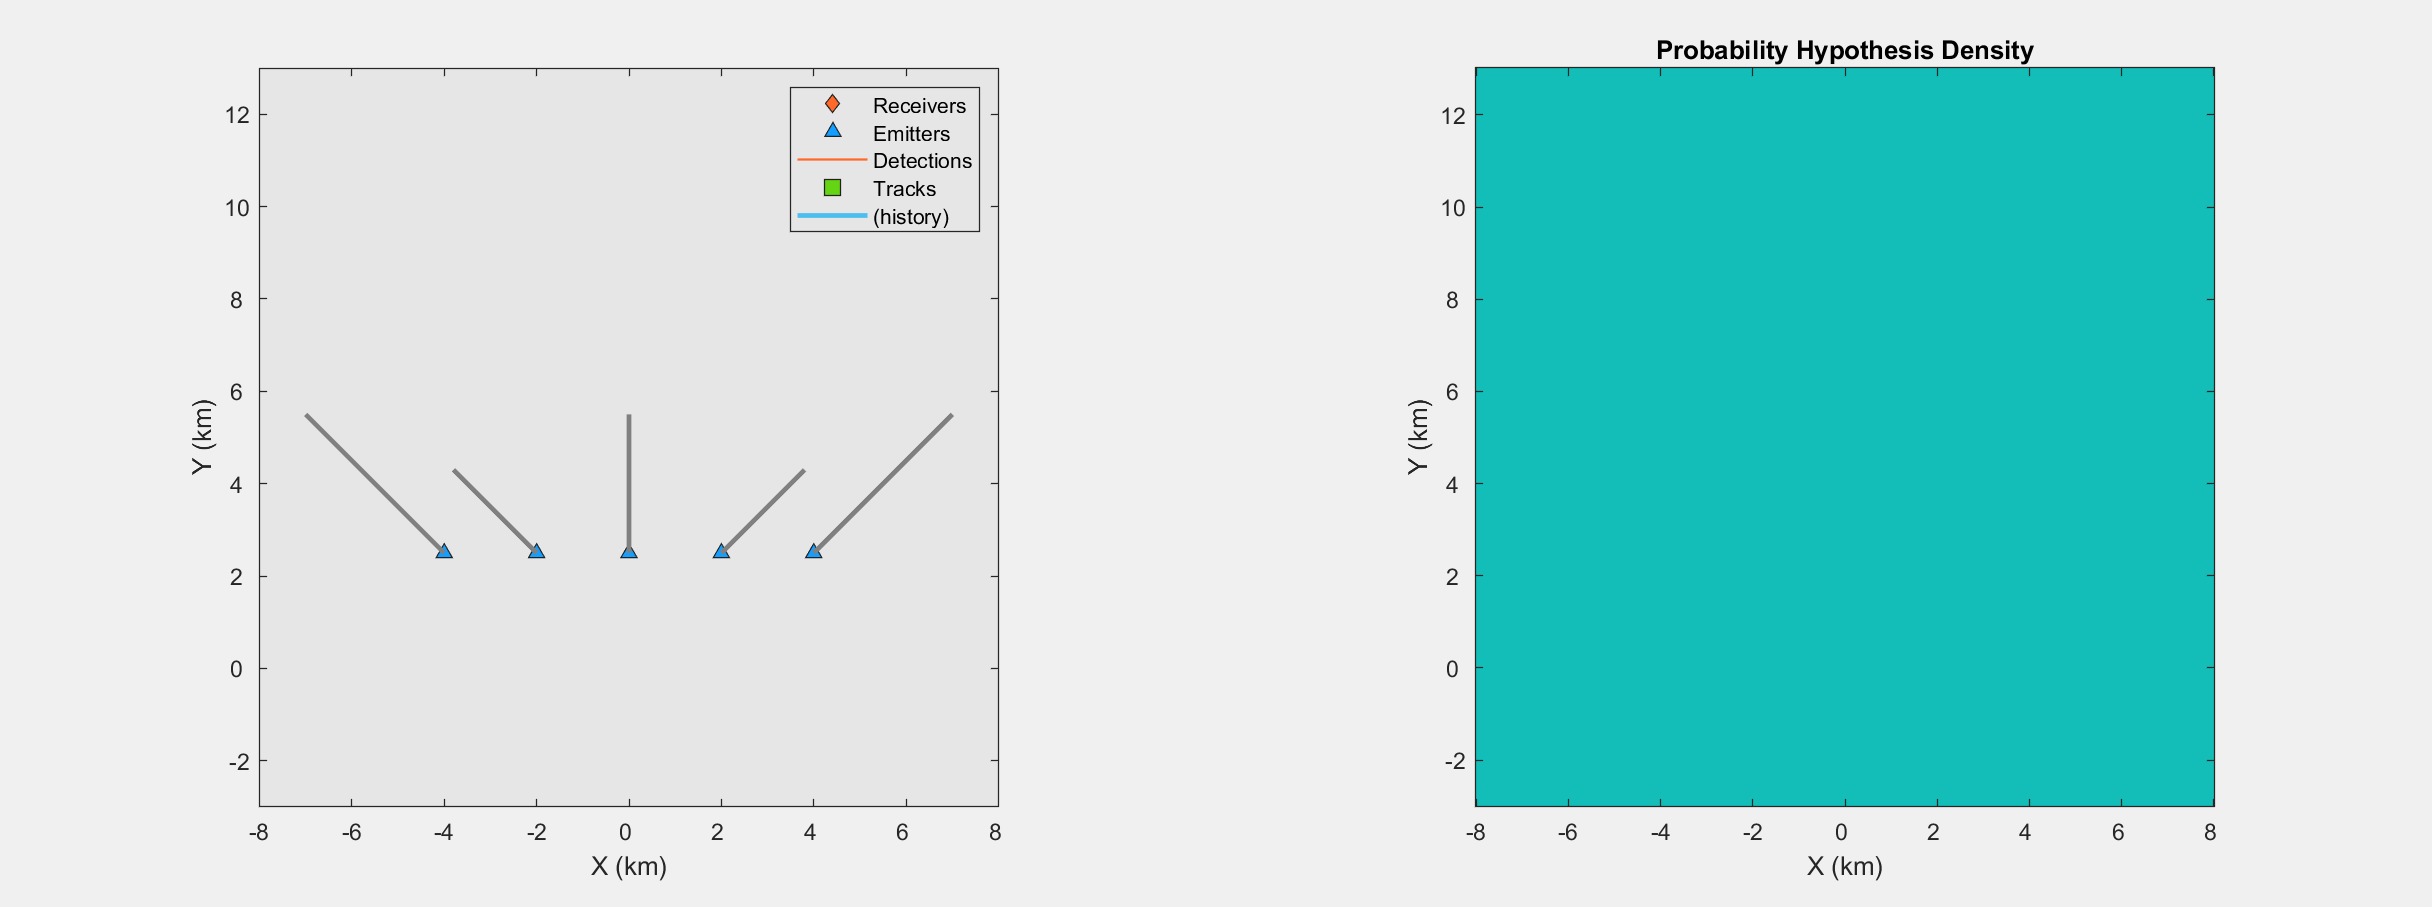

% Initialize variables
ospa2 = zeros(0,1);
cardOspa2 = zeros(0,1);
locOspa2 = zeros(0,1);
tracks = struct.empty(0,1);
phd = initcvgmphd;

% Measurement accuracy (deg^2)
measNoise = 2;

% Run the scenario 
while advance(scenario)
    % Current time
    time = scenario.SimulationTime;

    % Generate emissions from object
    [emTx, emConfigs] = emit(scenario);

    % Generate detections from emissions
    [detections, configs] = detect(scenario, emTx, emConfigs);

    % Add noise to detections
    detections = addNoise(detections, measNoise);

    if isLocked(tracker) || ~isempty(detections)
        % Update tracker
        tracks = tracker(detections, configs, time);

        % Get PHD filter from the tracker
        phd = getPHDFilter(tracker);
    end

    % Obtain ground truth
    platPoses = platformPoses(scenario);
    gTruth = platPoses(1:5);

    % Calculate OSPA(2) metric
    [ospa2(end+1,1),cardOspa2(end+1,1),locOspa2(end+1,1)] = ospaMetric(tracks, gTruth); %#ok<SAGROW> 

    % Update display
    display(scenario, tracks, detections, phd);
end

## Results

The images below show the ground truth, the true trajectories of the object, estimated tracks, and the PHD estimate in the 2-D position space. The first snapshot shows the result at the last time step of the scenario. You can see that tracker was able to maintain a track on every object. Also, the PHD estimate has strong peaks at true target locations, which implies that the tracker is confident about its estimate and does not have ambiguity between potential ghost targets and true targets.

showSnaps(display,time);

In the next few snapshots, you observe how the PHD is initialized at the first step from a single sensor and updated with new information from other sensors. In the first snapshot at time of 1/3 seconds, the peaks of the PHD follow the range-parameterized components based on the detections received from the first sensor.

showSnaps(display,1/3);

In the next two snapshots at time of 2/3 seconds and time of 1 second, notice how the PHD is updated with detections from the second and third sensor, respectively. After updating with detections from the second sensor, the PHD estimate is ambiguous because peaks from ghost objects are also present on the PHD. These peaks lie close to intersections between detections from the first sensor and the second sensor. Similarly, after the updating with detections from the third sensor, stronger peaks appear at positions close to the intersections of all three sensor measurements. After 1 second, the tracker estimate is still ambiguous as peaks are still present at some ghost object locations.

showSnaps(display,2/3);
showSnaps(display,1);

The tracker converges on the true peaks around 5 seconds as shown in the snapshot below. At this time, the tracker extracts tracks from these peaks, which are display in the plot on the left. 

showSnaps(display,5);

You also plot the OSPA(2) metric as a function of time to quantitatively assess the performance of the tracker. Notice that the OSPA(2) metric converges to a value less than 50, illustrating the average estimation accuracy per ground truth. The OSPA(2) metric is composed of two components, a localization component which measures the estimation accuracy of the trajectories and a cardinality component which measures the mismatch between numbers of true and estimated targets. The cardinality component of the metric shows that no false tracks or missed targets were present during this scenario simulation.

figure();
plot([ospa2 cardOspa2 locOspa2],'LineWidth',2);
grid on;
xlabel('Time step');
ylabel('Metric')
legend({'OSPA^{(2)}','Localization','Cardinality'});

## Summary

In this example, you learned how to simulate a scenario with asynchronous passive sensors and generate angle-only measurements. You simulated angle-only measurements from the sensors and fused them using a GM-PHD tracker. You qualitatively assessed the performance of the algorithms by visualizing the estimated tracks as well as the PHD. You also quantitatively assessed the performance by calculating the OSPA(2) metric. 

## References

[1] Bar-Shalom, Yaakov, Peter K. Willett, and Xin Tian. "Tracking and Data Fusion: A Handbook of Algorithms." (2011).

[2] Hamidi, Dimitri, et al. "Angle-Only, Range-Only and Multistatic Tracking Based on GM-PHD Filter." 2021 IEEE 24th International Conference on Information Fusion (FUSION). IEEE, 2021.

[3] Beard, Michael, Ba Tuong Vo, and Ba-Ngu Vo. "OSPA (2): Using the OSPA metric to evaluate multi-target tracking performance." *2017 International Conference on Control, Automation and Information Sciences (ICCAIS)*. IEEE, 2017.

## Supporting Functions

**addNoise**

This function adds noise to azimuth measurement of detections.

function dets = addNoise(dets,measNoise)
for i = 1:numel(dets)
    dets{i}.Measurement(1) = dets{i}.Measurement(1) + sqrt(measNoise)*randn;
    dets{i}.MeasurementNoise(1) = measNoise;
end
end

**initcvAngleOnlyGMPHD** 

This function initializes a range-parameterized Gaussian mixture PHD filter from an angle-only detection.

function filter = initcvAngleOnlyGMPHD(detection)
% Define range-parameterization parameters
numComponents = 10;
Rmin = 600;
Rmax = 5000;

% No components added to predictive birth intensity
filter = initcvgmphd;
if nargin == 0 
    return;
end

% Use initrpekf to easily get states and covariances of the filter bank
rpekf = initrpekf(detection{1}, numComponents, [Rmin Rmax]);

% Add components to the PHD filter
for i = 1:numComponents
    % Gaussian component for one range
    thisFilter = gmphd(rpekf.TrackingFilters{i}.State,...
        rpekf.TrackingFilters{i}.StateCovariance);

    % Append the filter to total PHD filter resulting in a Gaussian mixture.
    append(filter, thisFilter);
end

end


*Copyright 2022 The MathWorks, Inc.*